# Test script for basic TANDEM-STRAIGHT analysis and synthesis

clear
%   Please use this in "cell mode"

## Initialize conditions        %条件を初期化

directoryBase = [pwd '/'];
filename_save = 'sample3-2-1';
fileName = [filename_save '.wav'];
fileName_lab = [filename_save '_lab.txt'];

%分析対象の番号
number = 1;

label = sploadlabel(fileName_lab, 'sec');

noisy = 0; % If the speech material consists of low frequency noise, set this vaviable 1;
plotFigures = 1; % If you do not need plots, set this variable 0.

## Read speech data from a file   %ファイルから音声データを読み取る

[x,fs] = audioread([directoryBase fileName]);

time_start = label(number).time;        %音素の開始時間
time_stop = label(number + 1).time;     %音素の終了時間
point_start = round(time_start * fs);   %音素の開始ポイント数
point_stop = round(time_stop * fs);     %音素の終了ポイント数
interval = point_start:point_stop;      %特定の音素のポイント数
disp(size(interval));

           1        4984



disp(fs);

       44100




x = x(:,1); %   Make sure it is a comum vector.
%soundsc(x,fs) % Playback sound

## Extract source information    %ソース情報を抽出する

## Extract spectral informatiopn    %スペクトル情報を抽出する

filename_straight = ['STRAIGHT_ver2【' filename_save '】.mat'];

%matファイルの有無による処理
if (exist(filename_straight,'file') == 0)
    disp('matファイルが見つかりませんでした。');
    
    [f, rc, q, fs] = getstraight_ver3(x, fs, noisy);           %STRAIGHTスペクトル抽出部分の関数化
    save(filename_straight, 'f', 'rc', 'q', 'fs');            %STRAIGHTスペクトルのmatファイルを作成
else
    disp('matファイルが見つかりました。');
    file = load(filename_straight);
    
    f = file.f;
    fs = file.fs;
    rc = file.rc;
    q = file.q;
end

matファイルが見つかりました。


sgramSTRAIGHT = 10*log10(f.spectrogramSTRAIGHT);
maxLevel = max(max(sgramSTRAIGHT));
figure;
imagesc([0 f.temporalPositions(end)],[0 fs/2],max(maxLevel-80,sgramSTRAIGHT));
axis('xy')
set(gca,'fontsize',14);
xlabel('time (s)')
ylabel('frequency (Hz)');
spplotlabel(label, 'sec');
% str = ['スペクトログラム(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
str = ['スペクトログラム8kHz(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
% xlim([0 4.0]);                                         %x軸の値の範囲
xlim([time_start time_stop]);       %音素の範囲を表示
ylim([0 8000]);                                        %y軸の値の範囲
% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

pointPeriod = f.framePeriod * 1000;        %STRAIGHTスペクトルの間隔（例：1ms）を秒に変換
column_range = round(time_start*pointPeriod)+1:round(time_stop*pointPeriod);         %音素の開始・終了時間から列を求める（「pointPeriod」秒に1点）
cut_f.spectrogramSTRAIGHT = f.spectrogramSTRAIGHT(:, column_range);    %列の範囲を指定（STRAIGHTスペクトル）
cut_f.temporalPositions = f.temporalPositions(:, column_range);        %列の範囲を指定（時間表示）

row_len = size(cut_f.spectrogramSTRAIGHT, 1);       %行
column_len = size(cut_f.spectrogramSTRAIGHT, 2);    %列

down = (row_len-1)*2 * (fs/2) / fs / 2 + 1;                   %ダウンサンプリング
fs2 = fs/2;

%線形予測分析
for ii = 1:1:column_len
    spectrogram = cut_f.spectrogramSTRAIGHT(1:down, ii);           %列ごとのSTRAIGHTスペクトル
    point = length(spectrogram)-1:-1:2;                            %反転させるため
    spectrogram_symmetric = [spectrogram; spectrogram(point)];     %左右対称
    spectrogram_symmetric_ifft = ifft(spectrogram_symmetric);      %逆フーリエ変換 ⇒ 自己相関関数
    r = real(spectrogram_symmetric_ifft);                          %実部
    
    p = 22;                                                 %線形予測次数
    p_str = num2str(p);                                     %表示用
    alpha = levinson(r, p);                                 %線形予測係数ベクトル
    
    formants(1) = -1;
    formants(2) = -1;
    formants(3) = -1;
    bandwidth(1) = -1;
    bandwidth(2) = -1;
    bandwidth(3) = -1;
    
    %フォルマント推定
    frqs_range = 90;                %フォルマント周波数の条件（超える）
    bw_range = 400;                 %帯域幅の条件（未満）
    rts = roots(alpha);
    rts = rts(imag(rts)>=0);
    angz = atan2(imag(rts),real(rts));
    [frqs,indices] = sort(angz.*(fs2/(2*pi)));
    bw = -1/2*(fs2/(2*pi))*log(abs(rts(indices)));
    nn = 1;
    for kk = 1:length(frqs)
        if (frqs(kk) > frqs_range && bw(kk) < bw_range)
            formants(nn) = frqs(kk);
            bandwidth(nn) = bw(kk);
            nn = nn+1;
        end
    end
   
    formants_first(ii) = formants(1);
    formants_second(ii) = formants(2);
    formants_third(ii) = formants(3);
    
    bandwidth_first(ii) = bandwidth(1);
    bandwidth_second(ii) = bandwidth(2);
    bandwidth_third(ii) = bandwidth(3);
    
end

formants_first_average = mean(formants_first,2);
formants_second_average = mean(formants_second,2);
formants_third_average = mean(formants_third,2);
disp(formants_first_average);

  800.7254



disp(formants_second_average);

   1.1622e+03



disp(formants_third_average);

   2.6320e+03



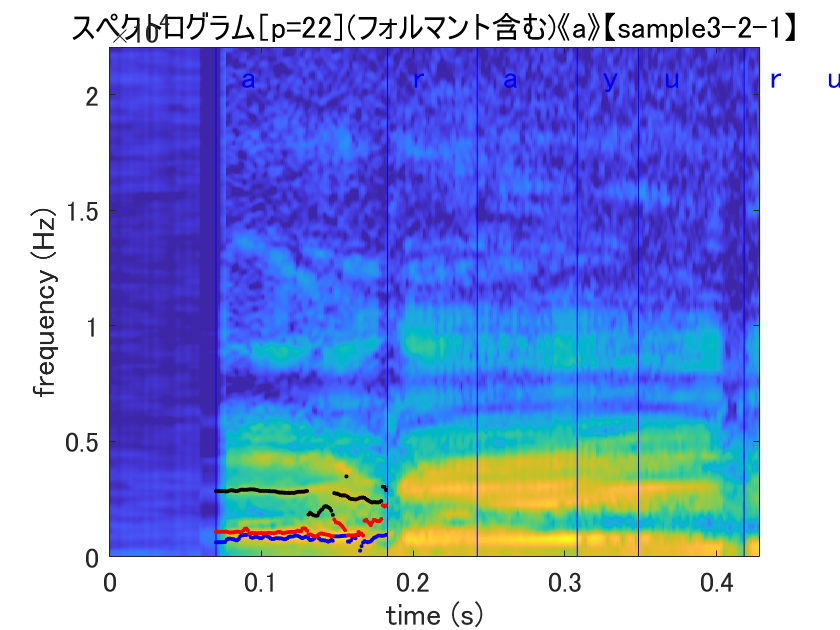


bandwidth_first_average = mean(bandwidth_first,2);
bandwidth_second_average = mean(bandwidth_second,2);
bandwidth_third_average = mean(bandwidth_third,2);

str = ['フォルマント・帯域幅 平均［p=' p_str '］《' label(number).phoneme '》【' filename_save '】.txt'];          %動的にファイル名を作成
fileID = fopen(str,'w');
fprintf(fileID,'%s: %f\n','第1フォルマント',formants_first_average);
fprintf(fileID,'%s: %f\n','第2フォルマント',formants_second_average);
fprintf(fileID,'%s: %f\n\n','第3フォルマント',formants_third_average);
fprintf(fileID,'%s: %f\n','帯域幅（第1フォルマント）',bandwidth_first_average);
fprintf(fileID,'%s: %f\n','帯域幅（第2フォルマント）',bandwidth_second_average);
fprintf(fileID,'%s: %f\n','帯域幅（第3フォルマント）',bandwidth_third_average);
fclose(fileID);

hold on
plot(cut_f.temporalPositions, formants_first, '.b');
plot(cut_f.temporalPositions, formants_second, '.r');
plot(cut_f.temporalPositions, formants_third, '.k');
str = ['スペクトログラム［p=' p_str '］(フォルマント含む)《' label(number).phoneme '》【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存
hold off

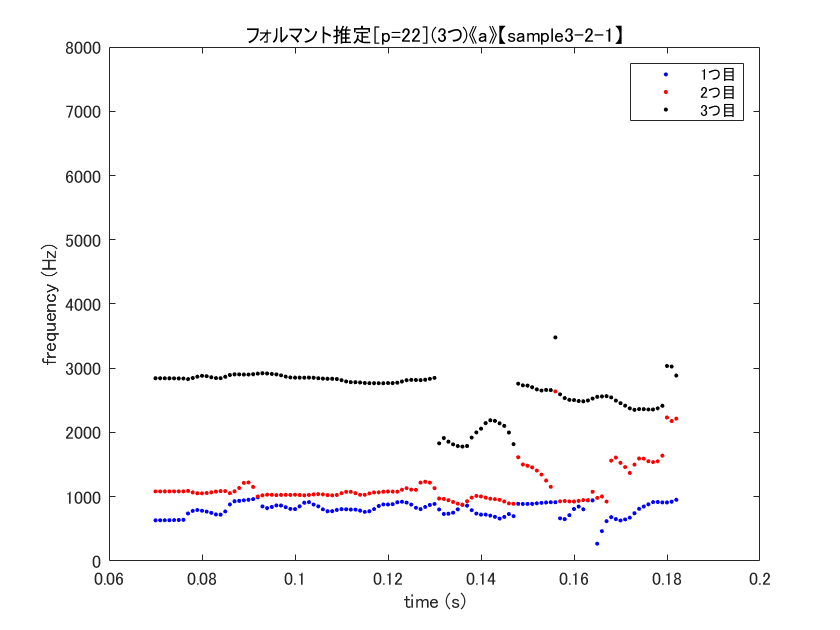


plot(cut_f.temporalPositions, formants_first, '.b');
hold on
plot(cut_f.temporalPositions, formants_second, '.r');
plot(cut_f.temporalPositions, formants_third, '.k');
hold off
xlabel('time (s)')
ylabel('frequency (Hz)');
str = ['フォルマント推定［p=' p_str '］(3つ)《' label(number).phoneme '》【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
legend('1つ目', '2つ目', '3つ目');                      %凡例
ylim([0 8000]);                                        %y軸の値の範囲

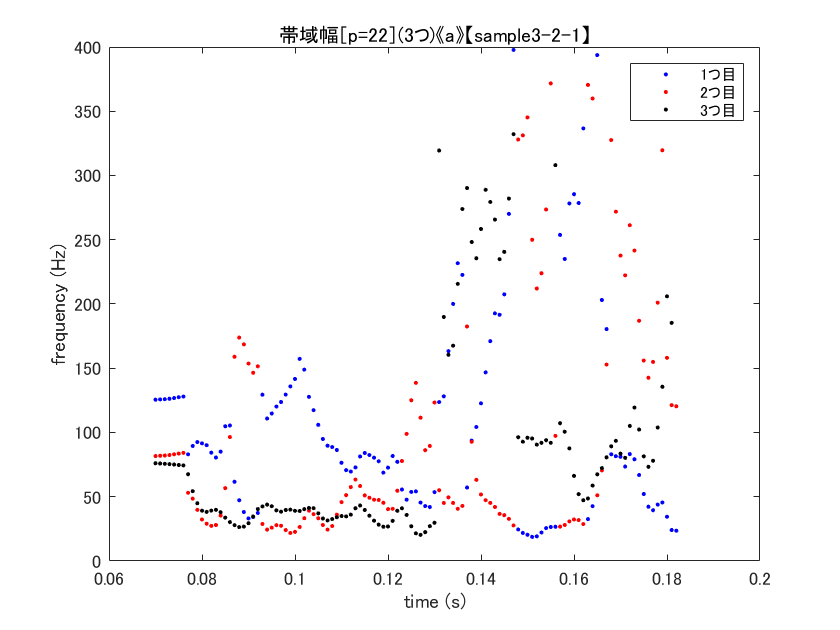

% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

plot(cut_f.temporalPositions, bandwidth_first, '.b');
hold on
plot(cut_f.temporalPositions, bandwidth_second, '.r');
plot(cut_f.temporalPositions, bandwidth_third, '.k');
hold off
xlabel('time (s)')
ylabel('frequency (Hz)');
str = ['帯域幅［p=' p_str '］(3つ)《' label(number).phoneme '》【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
legend('1つ目', '2つ目', '3つ目');                      %凡例
ylim([0 bw_range]);                                        %y軸の値の範囲

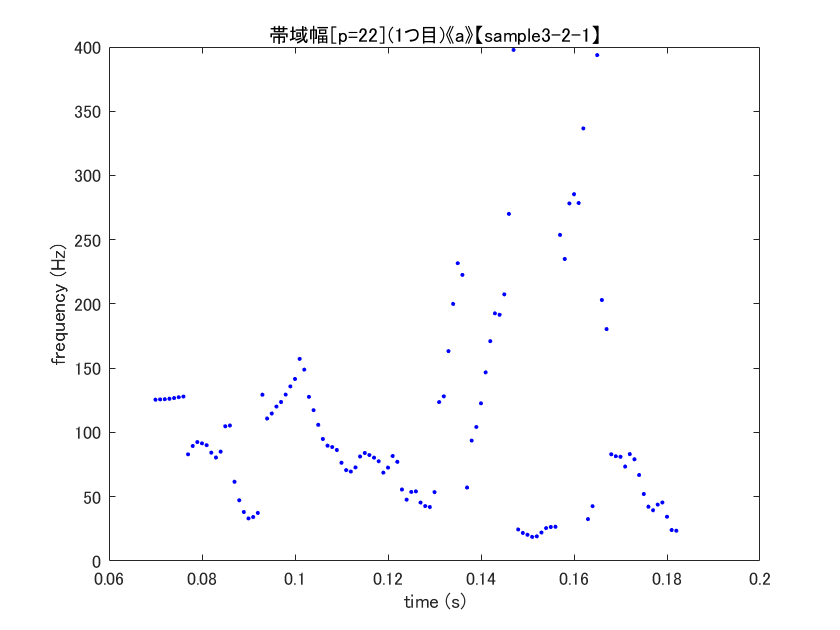

% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

plot(cut_f.temporalPositions, bandwidth_first, '.b');
xlabel('time (s)')
ylabel('frequency (Hz)');
str = ['帯域幅［p=' p_str '］(1つ目)《' label(number).phoneme '》【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
ylim([0 bw_range]);                                        %y軸の値の範囲

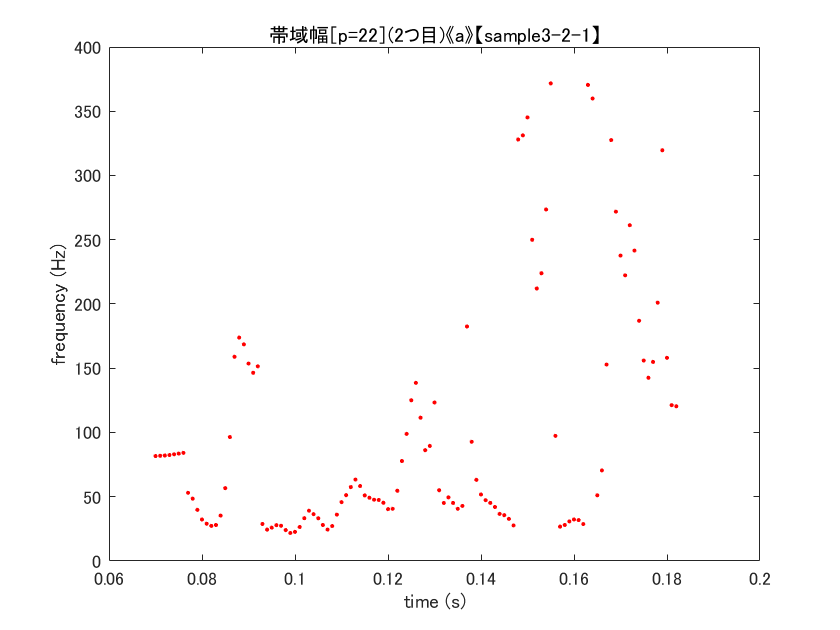

% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

plot(cut_f.temporalPositions, bandwidth_second, '.r');
xlabel('time (s)')
ylabel('frequency (Hz)');
str = ['帯域幅［p=' p_str '］(2つ目)《' label(number).phoneme '》【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
ylim([0 bw_range]);                                        %y軸の値の範囲

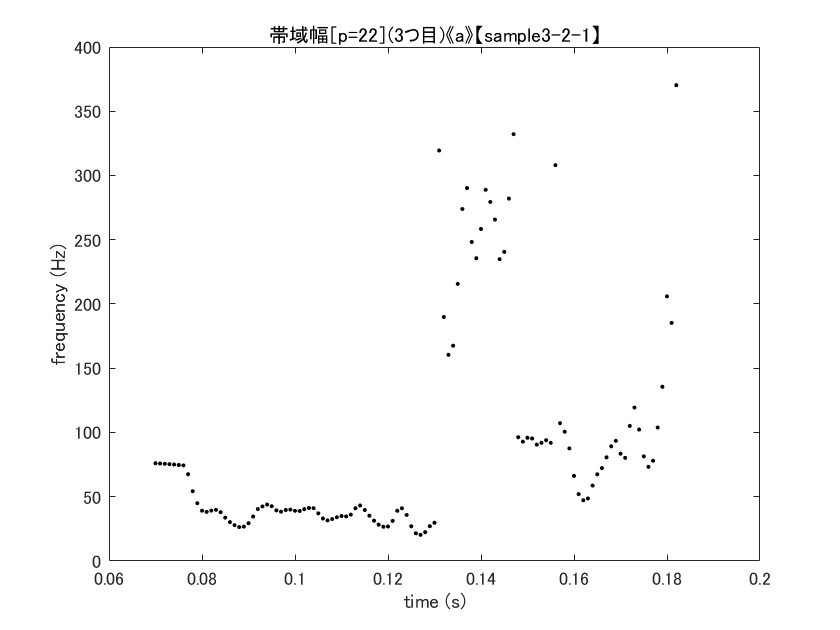

% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

plot(cut_f.temporalPositions, bandwidth_third, '.k');
xlabel('time (s)')
ylabel('frequency (Hz)');
str = ['帯域幅［p=' p_str '］(3つ目)《' label(number).phoneme '》【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル
ylim([0 bw_range]);                                        %y軸の値の範囲

% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

% s = exTandemSTRAIGHTsynthNx(q,f)
% sound(s.synthesisOut/max(abs(s.synthesisOut))*0.8,fs) % old implementation
% 
% s2 = exGeneralSTRAIGHTsynthesisR2(q,f) % new implementation
% sound(s2.synthesisOut/max(abs(s2.synthesisOut))*0.8,fs)